casadi_path = "C:\Users\tadas\Dropbox\MATLAB\casadi_win"

casadi_path = "C:\Users\tadas\Dropbox\MATLAB\casadi_win"

%casadi_path = "C:\Users\ge89liz\Dropbox\MATLAB\casadi_win"

% Add paths for DMP, OCP and CasADi dependencies
addpath(genpath('DMP'));
addpath(genpath('OMF'));
addpath(genpath(casadi_path));

% Define linear system
% It is assumed that B is full rank
A  = [-1 0; 0 -3];
B  = [1 0; 0 1];
x0 = [0.0;0.0];
x1 = [1.0;2.0];
t_end = 20;
dt = 0.001;

[u_training, x_training, time, cost_training] = analytic_solution(A,B,x0,x1,t_end,dt);
trj(:,1) = x_training(1,:);
trj(:,2) = x_training(2,:);

%% train DMP
tic
DMP.N = 80;
DMP = DMP_train(trj, time, DMP);
print_DMP(DMP);

kernel centers and widths: 
    1.0000    0.0187
    0.9750    0.0183
    0.9506    0.0178
    0.9269    0.0174
    0.9037    0.0169
    0.8811    0.0165
    0.8591    0.0161
    0.8376    0.0157
    0.8167    0.0153
    0.7962    0.0149
    0.7763    0.0146
    0.7569    0.0142
    0.7380    0.0138
    0.7196    0.0135
    0.7016    0.0132
    0.6840    0.0128
    0.6669    0.0125
    0.6503    0.0122
    0.6340    0.0119
    0.6182    0.0116
    0.6027    0.0113
    0.5876    0.0110
    0.5729    0.0107
    0.5586    0.0105
    0.5447    0.0102
    0.5310    0.0100
    0.5178    0.0097
    0.5048    0.0095
    0.4922    0.0092
    0.4799    0.0090
    0.4679    0.0088
    0.4562    0.0086
    0.4448    0.0083
    0.4337    0.0081
    0.4228    0.0079
    0.4123    0.0077
    0.4020    0.0075
    0.3919    0.0073
    0.3821    0.0072
    0.3726    0.0070
    0.3633    0.0068
    0.3542    0.0066
    0.3453    0.0065
    0.3367    0.0063
    0.3283    0.0062
    0.3201    0.0060
    0.

t_elapsed = toc;
disp(['DMP training time: ', num2str(t_elapsed)]);

DMP training time: 0.33403


## Generalize DMP for a given goal

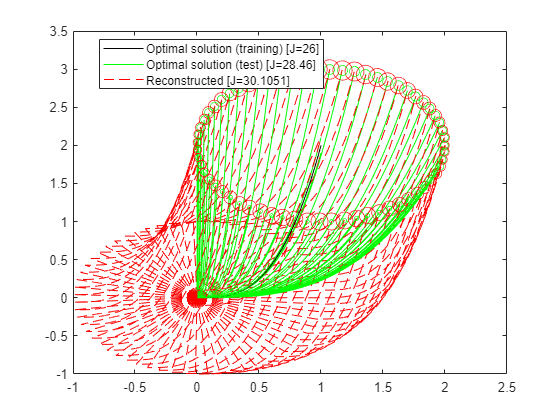

goal_x = 1;
goal_y = 2.1;
goal = [goal_x ; goal_y];
DMP.goal = goal;

%% integrate DMP
% initialize the DMP state
S.x = 1; S.y = DMP.y0; S.z = DMP.dy0*DMP.tau;
t = 0;
TRJ = [S.y]; TT = [t]; TRJD = [DMP.dy0];
% reconstruct the trajectory by Euler integration (F times higher than
% the trajectory sampling rate)
F = 1;
dt = dt / F;
tic
while t < t_end
  for i = 1:F
    S = DMP_integrate(DMP, S, dt);
    t = t + dt;
  end
  TT = [TT; t];
  TRJ = [TRJ; S.y];
end

%% calculate control associated to DMP
TRJdot = [gradient(TRJ(:,1), dt) ...
          gradient(TRJ(:,2), dt)];


% Needs to assume that the system is:
% - fully actuated, over-actuated or 
% - differentially flat
DMP_u = pinv(B)*(TRJdot' - A*TRJ'); 
DMP_cost = trapz(TT, vecnorm(DMP_u).^2);

[u_test, x_test, ~, cost_test] = analytic_solution(A,B,x0,goal,t_end,dt);
cost_training_N = trapz(time, vecnorm(u_training).^2);
cost_test_N = trapz(time, vecnorm(u_test).^2);

%% display results
% Compare trajectories 
figure(1)
hold off

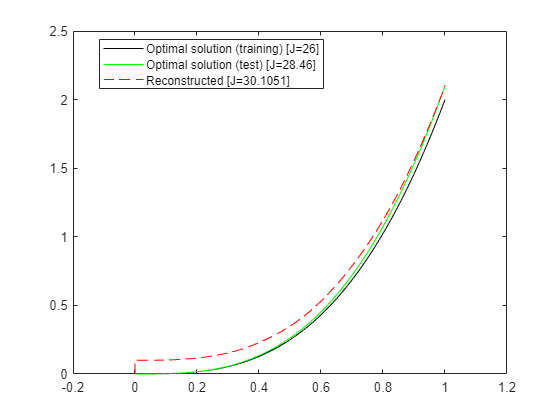

plot(x_training(1,:), x_training(2,:),'k', ...
     x_test(1,:), x_test(2,:), 'g', ...
     TRJ(:,1), TRJ(:,2), 'r--')

legend(['Optimal solution (training) [J=' num2str(double(cost_training)) ']'],  ...
       ['Optimal solution (test) [J=' num2str(double(cost_test)) ']'], ...
       ['Reconstructed [J=' num2str(DMP_cost) ']']);

legend("Position",[0.17631,0.78698,0.40179,0.11905])

## Test many DMP goals to test generalization

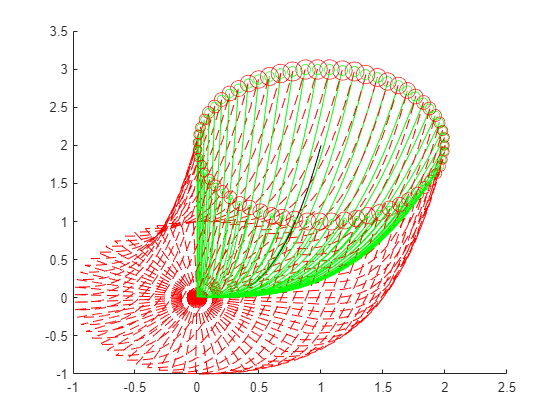

figure(2);
hold on;

cost_training_N = trapz(time, vecnorm(u_training).^2);
plot(x_training(1,:), x_training(2,:),'k');

for alpha=0:0.1:2*pi
    goal_x = x1(1) + 1*cos(alpha);
    goal_y = x1(2) + 1*sin(alpha);
    goal = [goal_x ; goal_y];
    DMP.goal = goal;
    
    [TRJ, TT] = DMP_trajectory(DMP, dt, t_end);
    
    DMP_cost = compute_cost(TRJ, dt, B, A, TT);
    
    [u_test, x_test, ~, cost_test] = analytic_solution(A,B,x0,goal,t_end,dt);
    cost_test_N = trapz(time, vecnorm(u_test).^2);
    
    plot(x_test(1,:), x_test(2,:), 'g', ...
         TRJ(:,1), TRJ(:,2), 'r--');
    scatter(goal_x, goal_y, ...
            cost_test_N,"green");
    scatter(goal_x, goal_y, ...
            DMP_cost,"red");
end

## Auxiliar functions

function [TRJ, TT] = DMP_trajectory(DMP, dt, t_end)
%% integrate DMP
% initialize the DMP state
S.x = 1; S.y = DMP.y0; S.z = DMP.dy0*DMP.tau;
t = 0;
TRJ = [S.y]; TT = [t]; TRJD = [DMP.dy0];
% reconstruct the trajectory by Euler integration (F times higher than
% the trajectory sampling rate)
F = 1;
dt = dt / F;
while t < t_end
    for i = 1:F
        S = DMP_integrate(DMP, S, dt);
        t = t + dt;
    end
    TT = [TT; t];
    TRJ = [TRJ; S.y];
end
end

function DMP_cost = compute_cost(TRJ, dt, B, A, TT)
%% calculate control associated to DMP
TRJdot = [gradient(TRJ(:,1), dt) ...
    gradient(TRJ(:,2), dt)];

% Needs to assume that the system is:
% - fully actuated, over-actuated or 
% - differentially flat
DMP_u = pinv(B)*(TRJdot' - A*TRJ'); 
DMP_cost = trapz(TT, vecnorm(DMP_u).^2);
end

% Generates optimal control problem
function [u,x,t,cost] = analytic_solution(A,B,x0,x1,T,dt)
    syms t v
    
    W = int(expm(A*t)*(B*B')*expm(A'*t),[0,T]);
    % Check condition number for debug:
    % cond(vpa(W))
    z = -B'*expm(A'*(T-t))/W;
    
    % u(t) = -B'*e^[A(T-t)]*inv(W)*(e^[AT]*x0 - x1)
    u = z*(expm(A*T)*x0 - x1);
    
    f = int( expm(A*(t-v))*B*subs(u,t,v) , v, 0, t);
    
    % x'(t) = Ax(t) + f(t)
    x = matlabFunction(expm(A*t)*x0 + f);
    u = matlabFunction(u);
    
    cost = vpa((expm(A*T)*x0 - x1)'*inv(W')*(expm(A*T)*x0 - x1));
    
    t = 0:dt:T;
    x = x(t);
    u = u(t);
end 